#  Homework 5: RRR elbow type Robot

**Mostafa Osama Ahmed**

**Innopolis University - DoNRS course**

Github Link: 

https://github.com/mostafa-metwaly/DoNRs-HW6

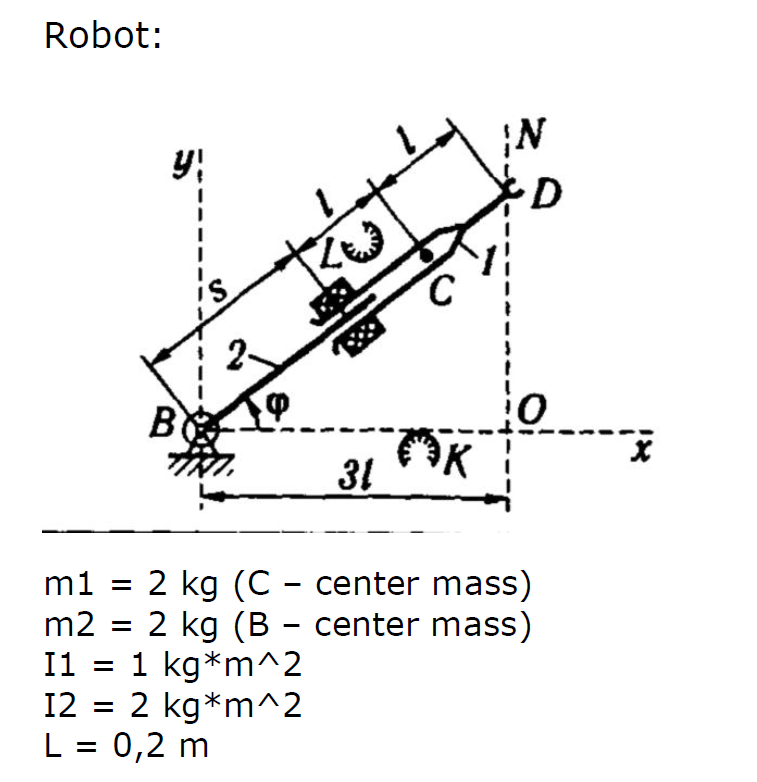

## Solving direct dynamic problem using Lagrange-Euler method

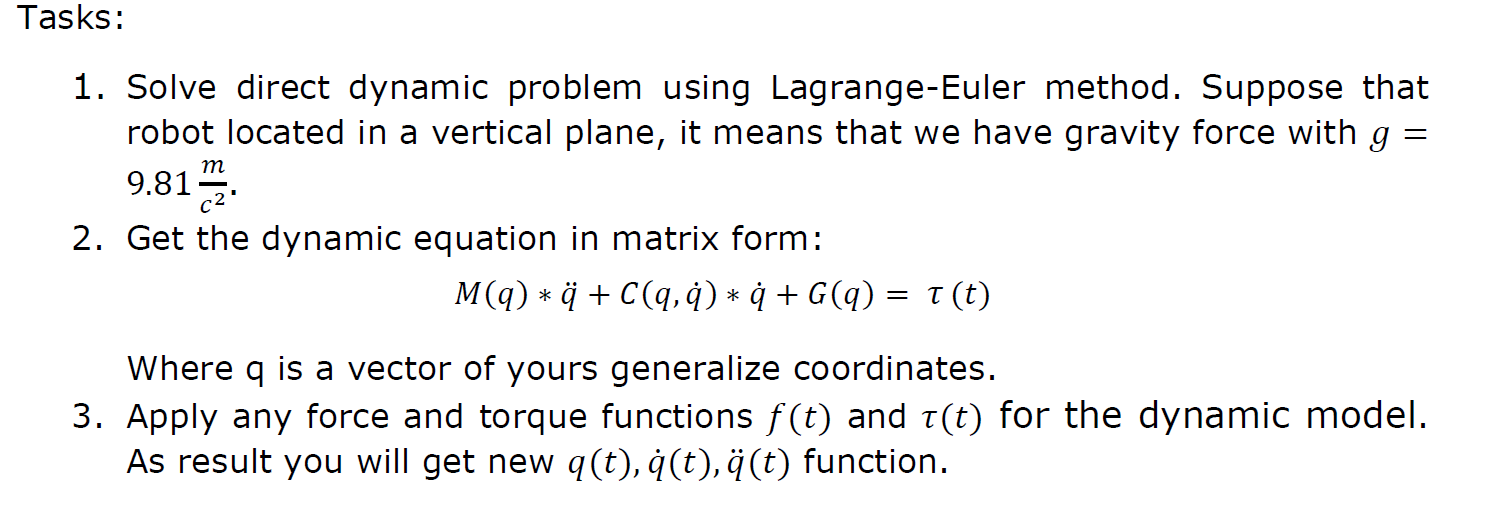

clear all;close all;clc;


syms m1 m2 q1 q2 dq1 dq2 ddq1 ddq2 I1 I2 L1 L2 d1 d2 g real

% m1=2;
% m2=2;
% I1=1;
% I2=2;
% L1=0.2;
% g=9.81;


### Skew theory

First find origin of each joint

FK:

T00= eye(4)

T00 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T01= Rz(q1)

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0c1= Rz(q1)

$$T0c1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02= Rz(q1)*Tx(q2)*Tx(L2)

$$T02 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & L_{2}\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & L_{2}\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0c2= Rz(q1)*Tx(q2)*Tx(d2)

$$T0c2 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & d_{2}\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & d_{2}\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Origins as position component of FK

O0 = T00(1:3,4)

O0 =      0
     0
     0



O1 = T01(1:3,4)

$$O1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Oc1 = T0c1(1:3,4)

$$Oc1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

O2 = simplify(T02(1:3,4))

$$O2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(L_{2}+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(L_{2}+q_{2}\right)\\ 0 \end{array}\right)$$

Oc2 = simplify(T0c2(1:3,4))

$$Oc2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)\\ 0 \end{array}\right)$$

Find rotation (translation in case of prismatic joint) axis Z from transformation, note the coloumn! Its should correspond to the joint axis

Z0 = T00(1:3,3) % 3rd coloumn corresponds to Rz

Z0 =      0
     0
     1


Zc1 = T0c1(1:3,3) % 3rd coloumn corresponds to Rz

$$Zc1 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

Zc2 = T0c2(1:3,1) % 1st coloumn corresponds to Tx

$$Zc2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$



R00=T00(1:3,1:3)

R00 =      1     0     0
     0     1     0
     0     0     1


R0c1=T0c1(1:3,1:3)

$$R0c1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R0c2=T0c2(1:3,1:3)

$$R0c2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

#### Full Jacobian




Zer = [0 0 0]';

Jv1 = [cross(Zc1,(Oc1-O0)), Zer]

$$Jv1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

Jv2 = [ cross(Zc1,(Oc2-O0)),Zc2]

$$Jv2 = \left(\begin{array}{cc} -\sin\left(q_{1}\right)\,\left(d_{2}+q_{2}\right) & \cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\left(d_{2}+q_{2}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$


Jw1 = [Zc1, Zer]

$$Jw1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

Jw2 = [Zc1, Zer]

$$Jw2 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

###  Euler-Lagrange Equation


q = [q1;q2];


#### Kinetic Energy Equation

D1 = m1*Jv1'*Jv1 + Jw1'*R0c1*I1*R0c1'*Jw1

$$D1 = \left(\begin{array}{cc} I_{1} & 0\\ 0 & 0 \end{array}\right)$$

D2 = m2*Jv2'*Jv2 + Jw2'*R0c2*I2*R0c2'*Jw2

$$D2 = \left(\begin{array}{cc} I_{2}+m_{2}\,{\cos\left(q_{1}\right)}^{2}\,{\left(d_{2}+q_{2}\right)}^{2}+m_{2}\,{\sin\left(q_{1}\right)}^{2}\,{\left(d_{2}+q_{2}\right)}^{2} & 0\\ 0 & m_{2}\,{\cos\left(q_{1}\right)}^{2}+m_{2}\,{\sin\left(q_{1}\right)}^{2} \end{array}\right)$$

D=D1+D2;

D=simplify(D)

$$D = \left(\begin{array}{cc} m_{2}\,{d_{2}}^{2}+2\,m_{2}\,d_{2}\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

#### Potentioal Energy Equation

P1 = 0;
P2 = m2*g*((d2 +q2)*sin(q1));
P = P1+P2

$$P = g\,m_{2}\,\sin\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)$$


G1 = diff(P, q1)

$$G1 = g\,m_{2}\,\cos\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)$$

G2 = diff(P, q2)

$$G2 = g\,m_{2}\,\sin\left(q_{1}\right)$$


G = [G1; G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$


dq = [dq1; dq2];
ddq = [ddq1; ddq2];

#### calculating coriolios force

C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} {\mathrm{dq}}_{2}\,m_{2}\,\left(d_{2}+q_{2}\right) & {\mathrm{dq}}_{1}\,m_{2}\,\left(d_{2}+q_{2}\right)\\ -{\mathrm{dq}}_{1}\,m_{2}\,\left(d_{2}+q_{2}\right) & 0 \end{array}\right)$$

### Direct Dynamic equation

### Equation for Torque:


$$D\left(q_1 ,q_2 \right)\;\left\lbrack \begin{array}{c}
\ddot{q_1 } \\
\ddot{q_2 } 
\end{array}\right\rbrack +C\left(q_1 ,q_2 ,\dot{q_1 } ,\dot{q_2 } \right)\;\left\lbrack \begin{array}{c}
\dot{q_1 } \\
\dot{q_2 } 
\end{array}\right\rbrack +G\left(q_1 ,q_2 \right)=\left\lbrack \begin{array}{c}
\tau \\
F
\end{array}\right\rbrack \;$$


tor =simplify( D*ddq+C*dq+G)

$$tor = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(m_{2}\,{d_{2}}^{2}+2\,m_{2}\,d_{2}\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)+g\,m_{2}\,\cos\left(q_{1}\right)\,\left(d_{2}+q_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\left(d_{2}+q_{2}\right)\\ -m_{2}\,\left(d_{2}+q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,m_{2}+g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$


D(q1,q2) = subs(D,{m1, m2, I1, I2, L2, d2},{2 2 1 2 0.2 0.1})

$$D(q1, q2) = \left(\begin{array}{cc} 2\,{q_{2}}^{2}+0.4000\,q_{2}+3.0200 & 0\\ 0 & 2 \end{array}\right)$$

C(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2, I1, I2, L2, d2},{2 2 1 2 0.2 0.1})

$$C(q1, q2, dq1, dq2) = \left(\begin{array}{c} 4\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(q_{2}+0.1000\right)\\ -2\,{{\mathrm{dq}}_{1}}^{2}\,\left(q_{2}+0.1000\right) \end{array}\right)$$

G(q1,q2) = subs(G ,{m1, m2, I1, I2, L2, d2, g},{2 2 1 2 0.2 0.1 9.81})

$$G(q1, q2) = \left(\begin{array}{c} 19.6200\,\cos\left(q_{1}\right)\,\left(q_{2}+0.1000\right)\\ 19.6200\,\sin\left(q_{1}\right) \end{array}\right)$$



n=200;
t = 0:0.1:(0.1*(n-1));
q1_0 = deg2rad(90);
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;


Adding forces and torques values

U = [ 0;  0];



for i = 1:n
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;

    ddq(:,i) = inv(D(q1_0, q2_0))*(U(:,1)-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    dq1_0=dq1p(i) + double(ddq(1)*dt);
    dq2_0=dq2p(i) + double(ddq(2)*dt);
    q1_0 = q1p(i) + dq1_0*dt;
    q2_0 = q2p(i) + dq2_0*dt;
end

Plotting the Position , velocity and acceleration of joints.

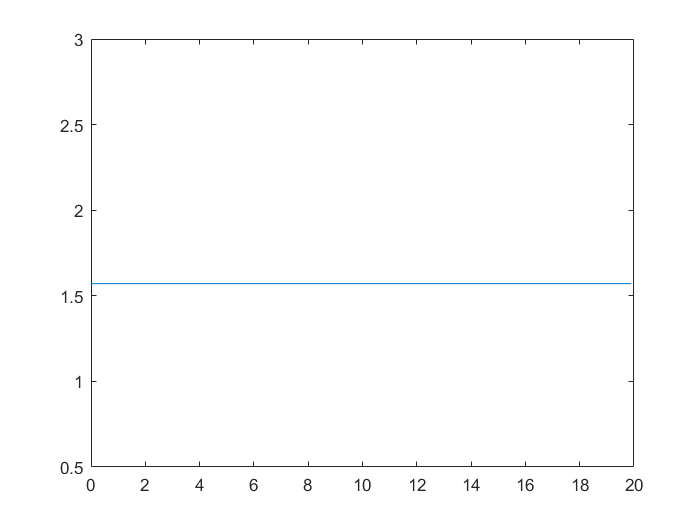


figure
plot(t,q1p)

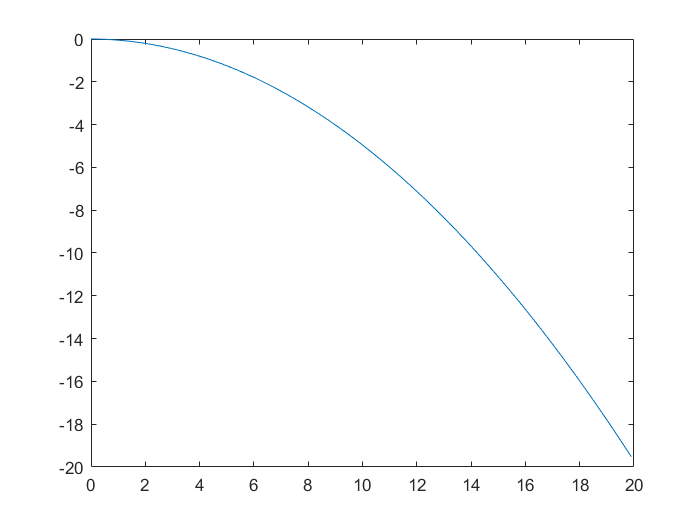

figure
plot(t,q2p)

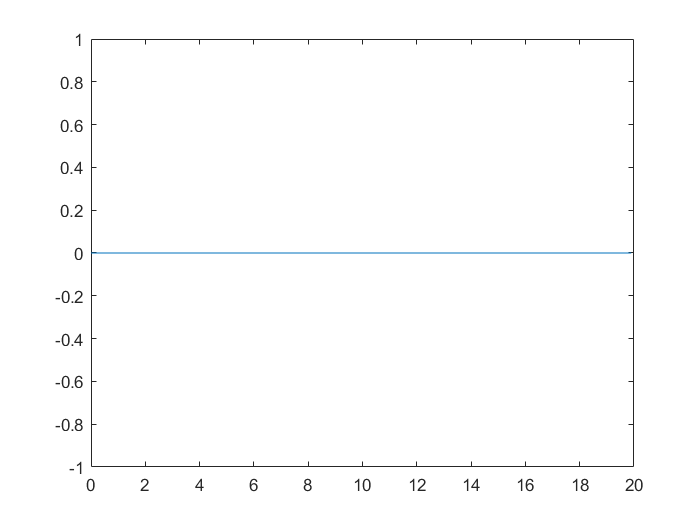

figure
plot(t,dq1p)

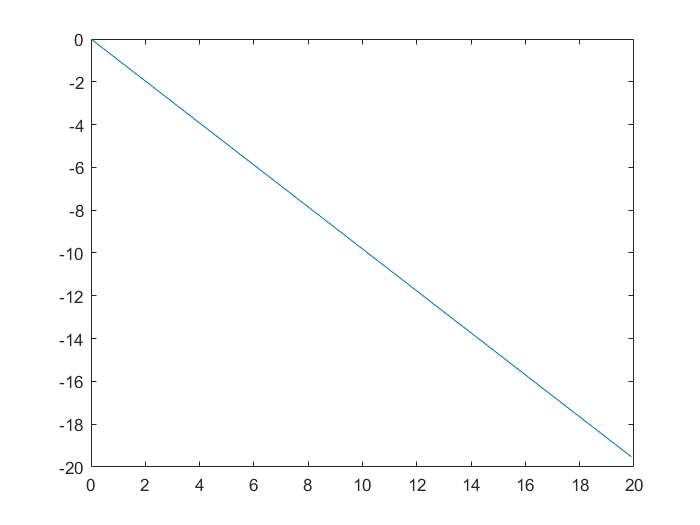

figure
plot(t,dq2p)

figure
plot(t,ddq(1,:))

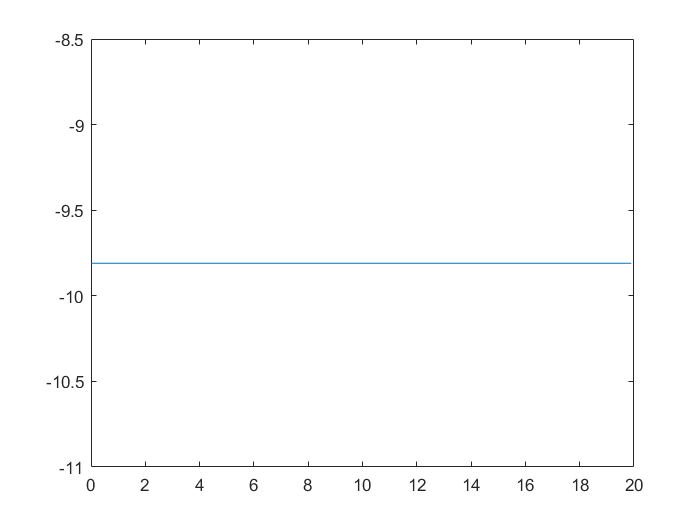

figure
plot(t,ddq(2,:))

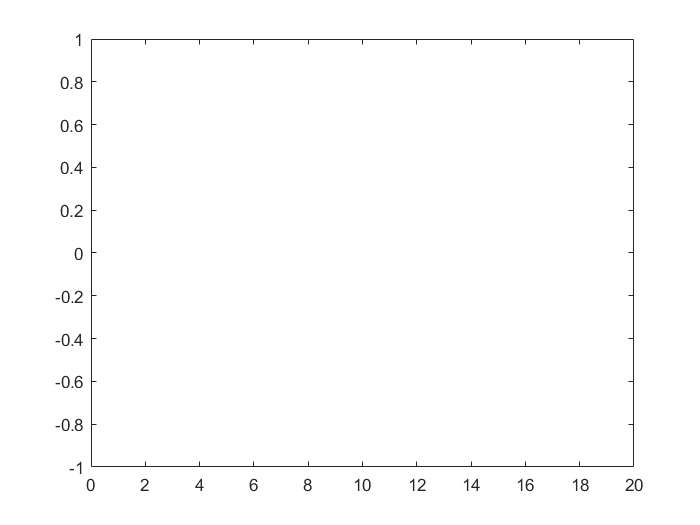


figure
plot(t,U(1,:))

figure
plot(t,U(2,:))

####  viewing the robot motion

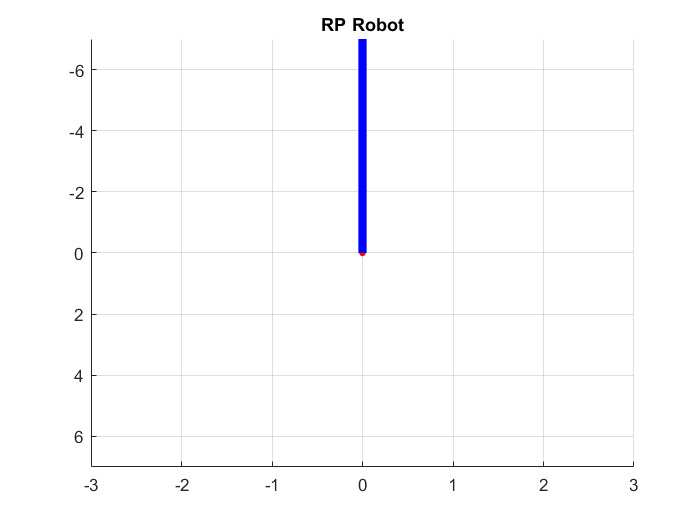




Q=[q1p ;q2p];
Vel=[dq1p ; dq2p ];
Acc=[ddq(1,:); ddq(2,:) ];
figure
for i=1:1:length(Q)
   draw_myrobot( Q(:,i)')
  
   pause(0.01)
   cla
   end   
 draw_myrobot( Q(:,i)')

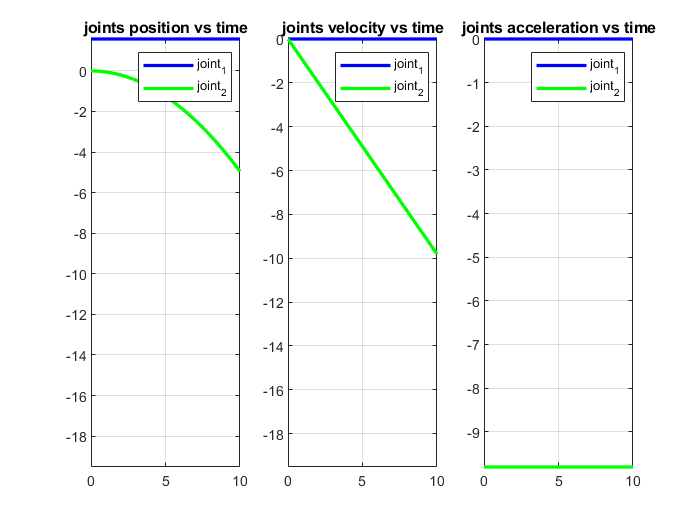

figure
subplot(1,3,1)
plot(t,Q(1,:),'b-','linewidth',2)
hold on
plot(t,Q(2,:),'g-','linewidth',2)
  grid on
title('joints position vs time')
legend('joint_1','joint_2' )
axis([0 10 -inf inf])

subplot(1,3,2)
plot(t,Vel(1,:),'b-','linewidth',2)
hold on
plot(t,Vel(2,:),'g-','linewidth',2)
 title('joints velocity vs time')
legend('joint_1','joint_2' )
grid on
axis([0 10 -inf inf])

subplot(1,3,3)
plot(t,Acc(1,:),'b-','linewidth',2)
hold on
plot(t,Acc(2,:),'g-','linewidth',2)
hold on
 title('joints acceleration vs time')
legend('joint_1','joint_2')
grid on
axis([0 10 -inf inf])

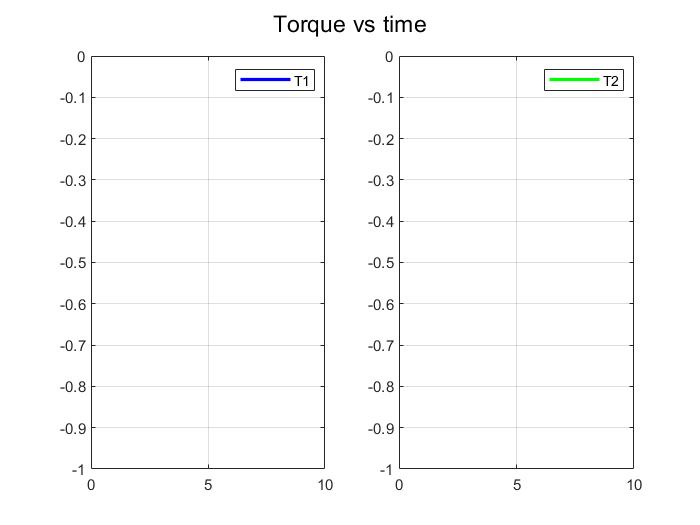


figure
subplot(1,2,1)
plot(t,U(1,:),'b-','linewidth',2)
hold on
legend('T1')
grid on
axis([0 10 -inf inf])
subplot(1,2,2)
plot(t,U(2,:),'g-','linewidth',2)
hold on
sgtitle('Torque vs time')
legend('T2')
grid on
axis([0 10 -inf inf])

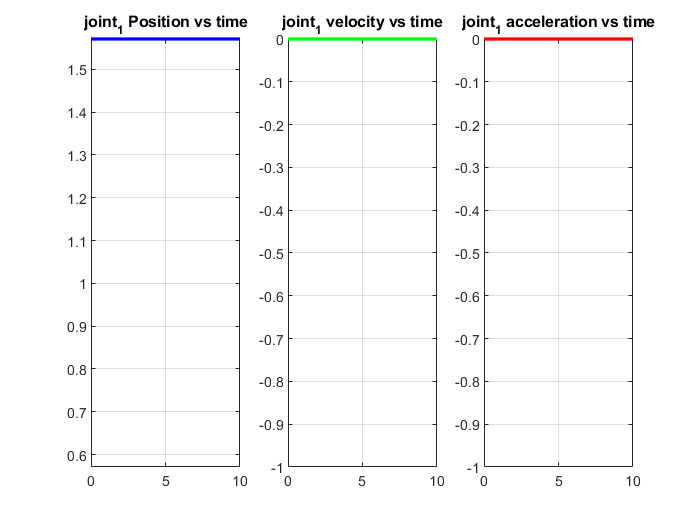


figure
hold on
subplot(1,3,1)
plot(t,Q(1,:),'b-','linewidth',2)
hold on
title('joint_1 Position vs time')
grid on
axis([0 10 -inf inf])
hold on
subplot(1,3,2)
plot(t,Vel(1,:),'g-','linewidth',2)
hold on
title('joint_1 velocity vs time')
grid on
axis([0 10 -inf inf])
subplot(1,3,3)
plot(t,Acc(1,:),'r-','linewidth',2)
title('joint_1 acceleration vs time')
grid on
axis([0 10 -inf inf])

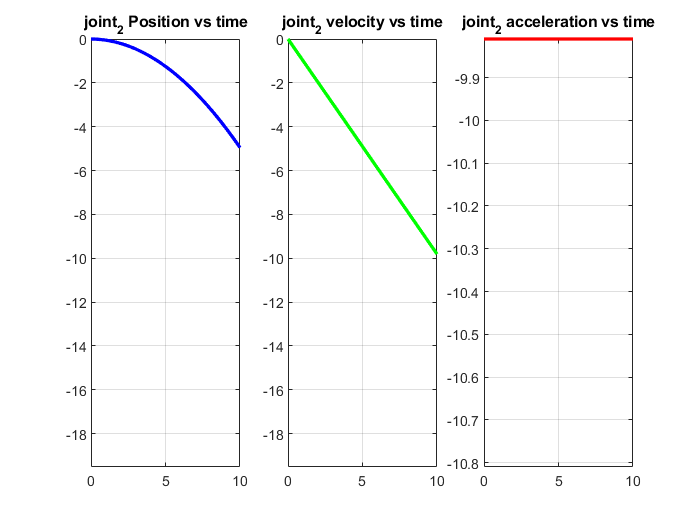


figure

hold on
subplot(1,3,1)
plot(t,Q(2,:),'b-','linewidth',2)
hold on
title('joint_2 Position vs time')
grid on
axis([0 10 -inf inf])
hold on
subplot(1,3,2)
plot(t,Vel(2,:),'g-','linewidth',2)
hold on
title('joint_2 velocity vs time')
grid on
axis([0 10 -inf inf])
subplot(1,3,3)
plot(t,Acc(2,:),'r-','linewidth',2)
title('joint_2 acceleration vs time')
grid on
axis([0 10 -inf inf])

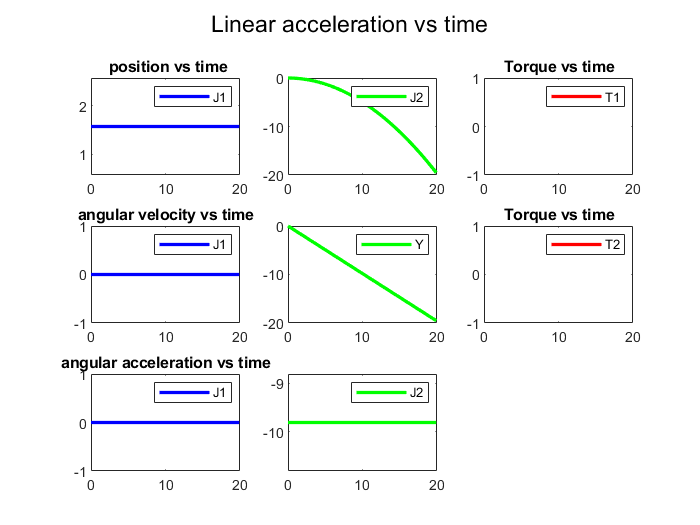



figure;
subplot(3,3,1);plot(t,Q(1,:),'b-','linewidth',2);title(' position vs time');legend('J1');
subplot(3,3,2);plot(t,Q(2,:),'g-','linewidth',2);sgtitle(' position vs time');legend('J2');
subplot(3,3,3);plot(t,U(1,:),'r-','linewidth',2 );title('Torque vs time');legend('T1');

subplot(3,3,4);plot(t,Vel(1,:),'b-','linewidth',2);title('angular velocity vs time');legend('J1');
subplot(3,3,5);plot(t,Vel(2,:),'g-','linewidth',2);sgtitle('Linear velocity vs time');legend('Y');
subplot(3,3,6);plot(t,U(2,:),'r-','linewidth',2 );title('Torque vs time');legend('T2');

subplot(3,3,7);plot(t,Acc(1,:),'b-','linewidth',2);title('angular acceleration vs time');legend('J1');
subplot(3,3,8);plot(t,Acc(2,:),'g-','linewidth',2);sgtitle('Linear acceleration vs time');legend('J2');
 hold off

Adding forces and torques functions

U2 = [ 20*sin(t); 1+cos(t)];



for i = 1:n
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;

    ddq(:,i) = inv(D(q1_0, q2_0))*(U2(:,i)-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    dq1_0=dq1p(i) + double(ddq(1)*dt);
    dq2_0=dq2p(i) + double(ddq(2)*dt);
    q1_0 = q1p(i) + dq1_0*dt;
    q2_0 = q2p(i) + dq2_0*dt;
end

Plotting the Position , velocity and acceleration of joints.

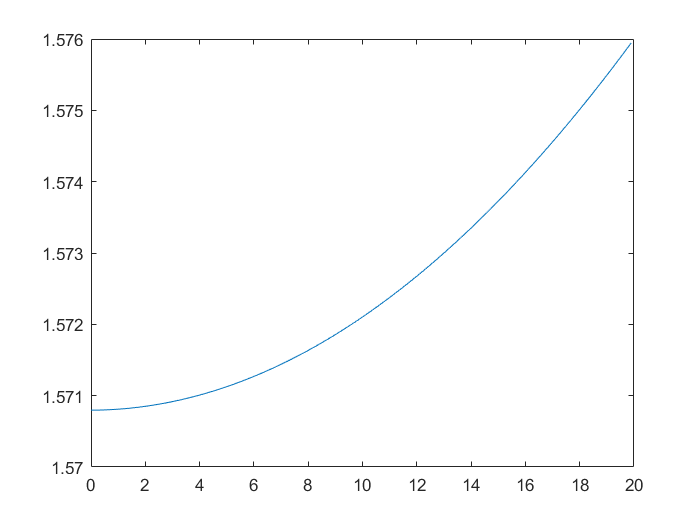


figure
plot(t,q1p)

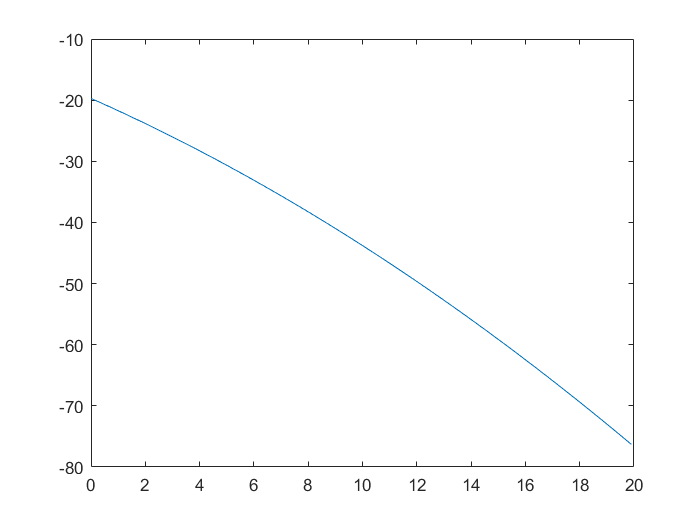

figure
plot(t,q2p)

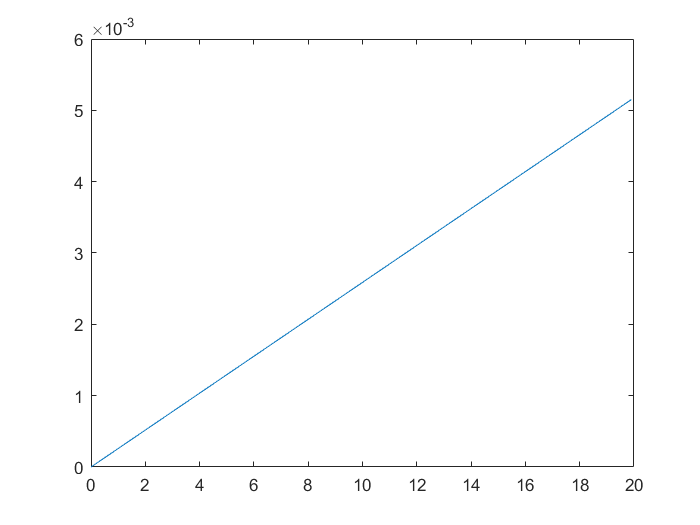

figure
plot(t,dq1p)

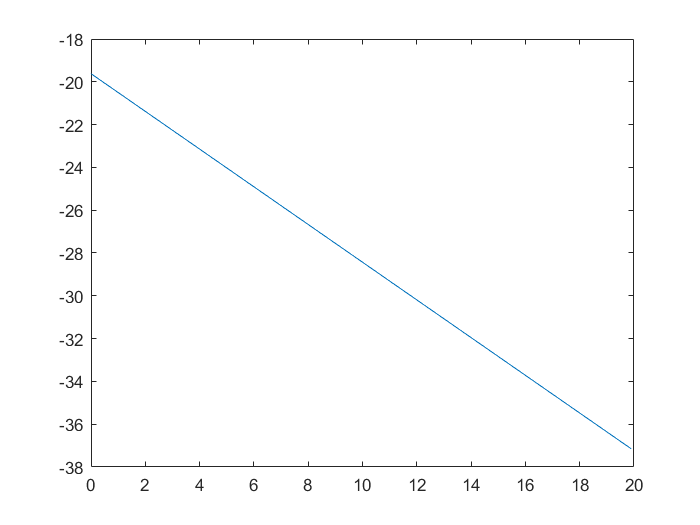

figure
plot(t,dq2p)

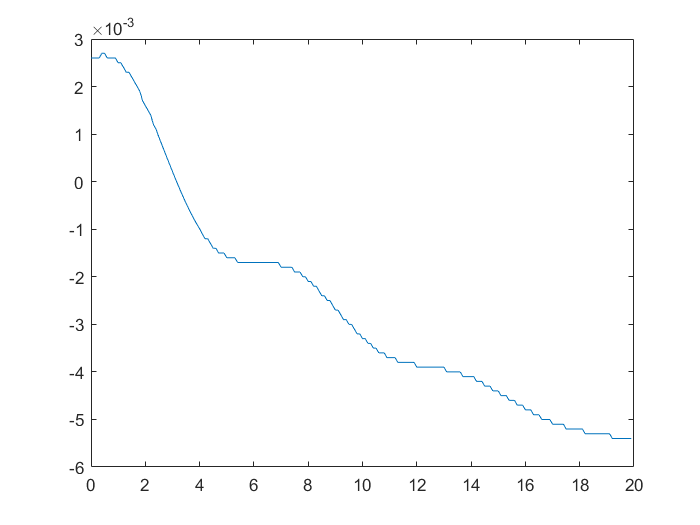

figure
plot(t,ddq(1,:))

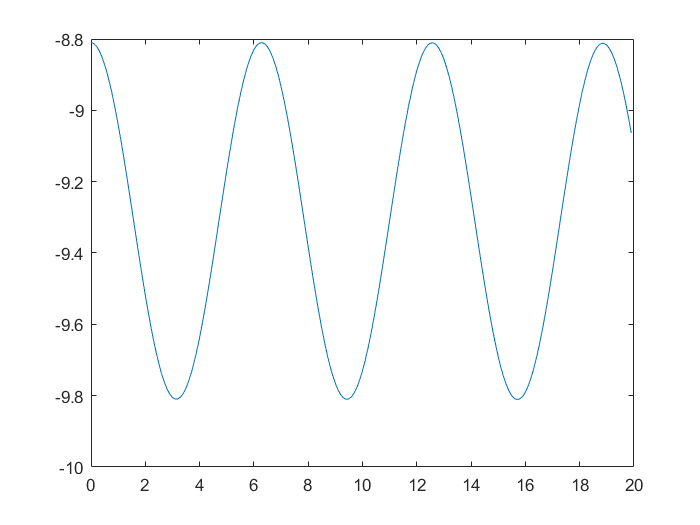

figure
plot(t,ddq(2,:))

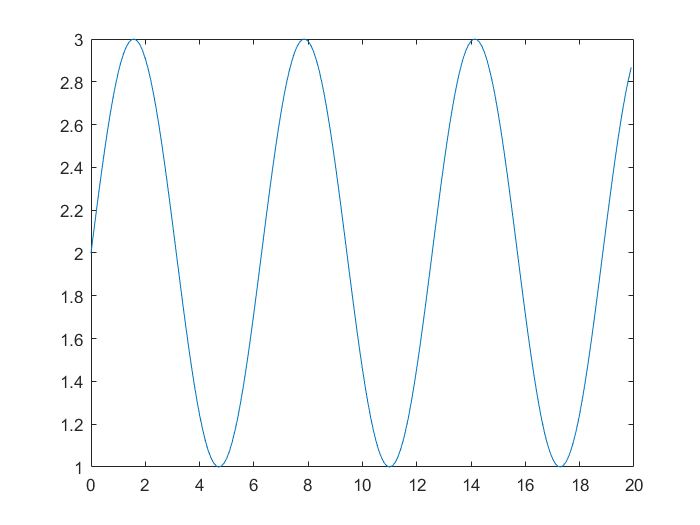


figure
plot(t,U2(1,:))

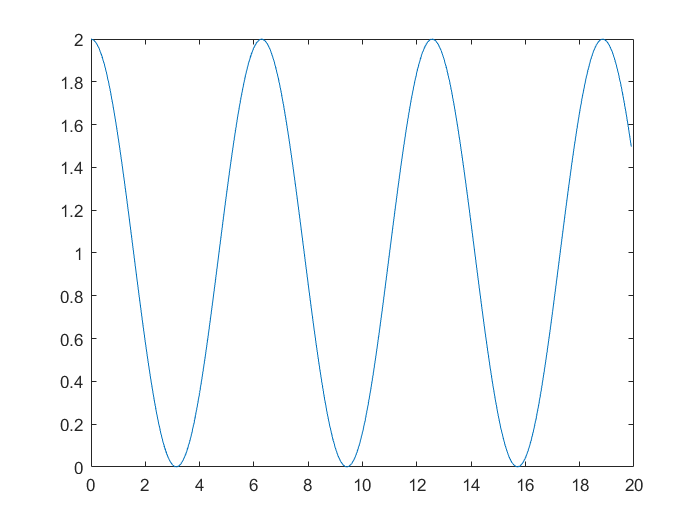

figure
plot(t,U2(2,:))

####  viewing the robot motion

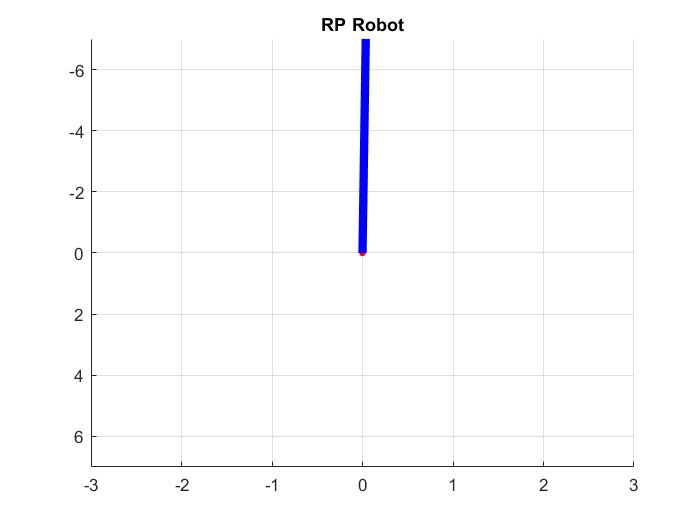




Q=[q1p ;q2p];
Vel=[dq1p ; dq2p ];
Acc=[ddq(1,:); ddq(2,:) ];
figure
for i=1:1:length(Q)
   draw_myrobot( Q(:,i)')
  
   pause(0.01)
   cla
   end   
 draw_myrobot( Q(:,i)')

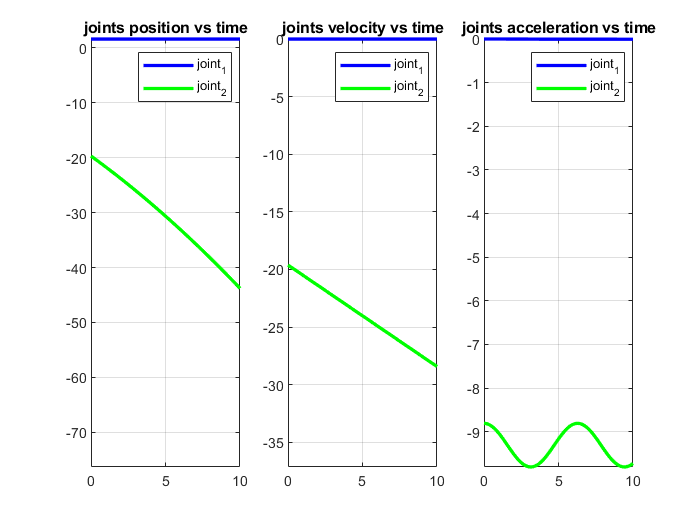

figure
subplot(1,3,1)
plot(t,Q(1,:),'b-','linewidth',2)
hold on
plot(t,Q(2,:),'g-','linewidth',2)
  grid on
title('joints position vs time')
legend('joint_1','joint_2' )
axis([0 10 -inf inf])

subplot(1,3,2)
plot(t,Vel(1,:),'b-','linewidth',2)
hold on
plot(t,Vel(2,:),'g-','linewidth',2)
 title('joints velocity vs time')
legend('joint_1','joint_2' )
grid on
axis([0 10 -inf inf])

subplot(1,3,3)
plot(t,Acc(1,:),'b-','linewidth',2)
hold on
plot(t,Acc(2,:),'g-','linewidth',2)
hold on
 title('joints acceleration vs time')
legend('joint_1','joint_2')
grid on
axis([0 10 -inf inf])

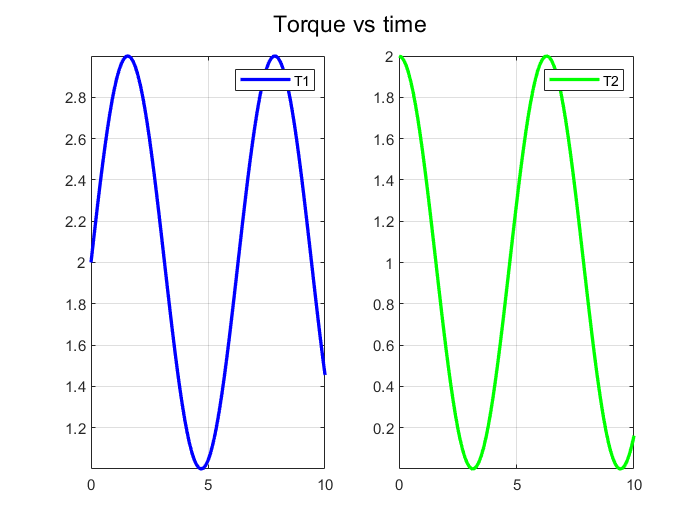


figure
subplot(1,2,1)
plot(t,U2(1,:),'b-','linewidth',2)
hold on
legend('T1')
grid on
axis([0 10 -inf inf])
subplot(1,2,2)
plot(t,U2(2,:),'g-','linewidth',2)
hold on
sgtitle('Torque vs time')
legend('T2')
grid on
axis([0 10 -inf inf])

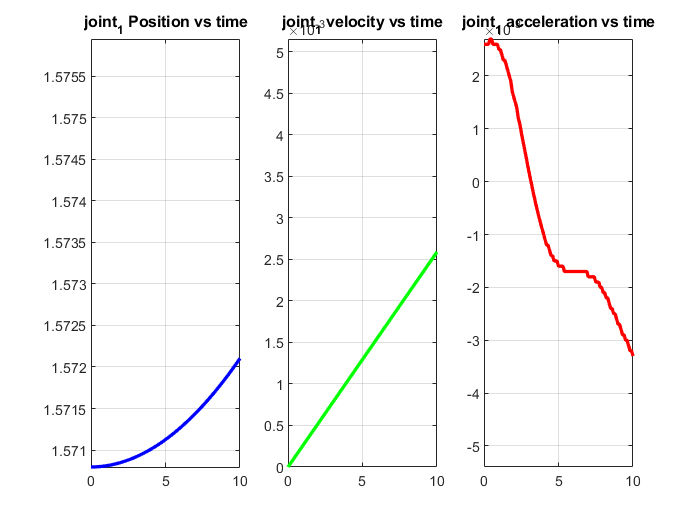


figure
hold on
subplot(1,3,1)
plot(t,Q(1,:),'b-','linewidth',2)
hold on
title('joint_1 Position vs time')
grid on
axis([0 10 -inf inf])
hold on
subplot(1,3,2)
plot(t,Vel(1,:),'g-','linewidth',2)
hold on
title('joint_1 velocity vs time')
grid on
axis([0 10 -inf inf])
subplot(1,3,3)
plot(t,Acc(1,:),'r-','linewidth',2)
title('joint_1 acceleration vs time')
grid on
axis([0 10 -inf inf])

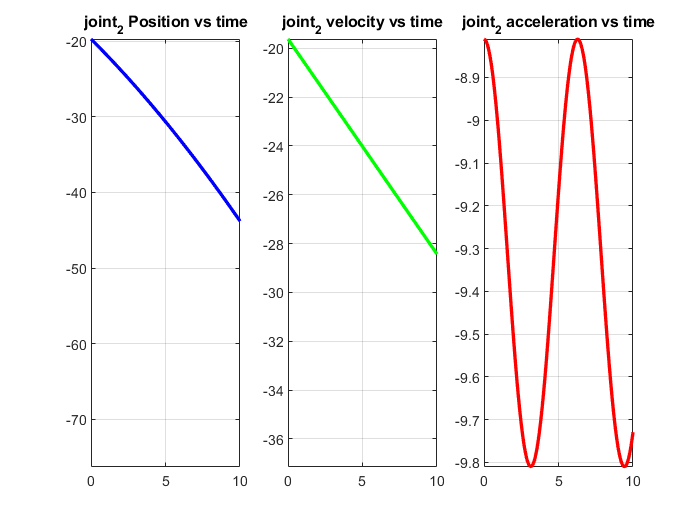


figure

hold on
subplot(1,3,1)
plot(t,Q(2,:),'b-','linewidth',2)
hold on
title('joint_2 Position vs time')
grid on
axis([0 10 -inf inf])
hold on
subplot(1,3,2)
plot(t,Vel(2,:),'g-','linewidth',2)
hold on
title('joint_2 velocity vs time')
grid on
axis([0 10 -inf inf])
subplot(1,3,3)
plot(t,Acc(2,:),'r-','linewidth',2)
title('joint_2 acceleration vs time')
grid on
axis([0 10 -inf inf])

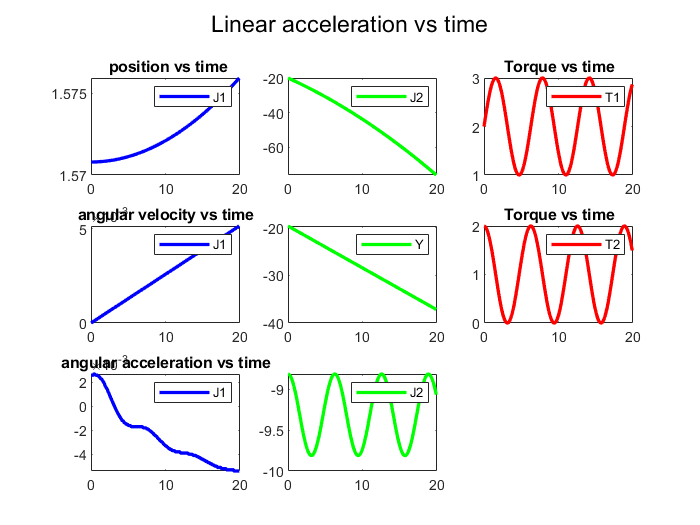



figure;
subplot(3,3,1);plot(t,Q(1,:),'b-','linewidth',2);title(' position vs time');legend('J1');
subplot(3,3,2);plot(t,Q(2,:),'g-','linewidth',2);sgtitle(' position vs time');legend('J2');
subplot(3,3,3);plot(t,U2(1,:),'r-','linewidth',2 );title('Torque vs time');legend('T1');

subplot(3,3,4);plot(t,Vel(1,:),'b-','linewidth',2);title('angular velocity vs time');legend('J1');
subplot(3,3,5);plot(t,Vel(2,:),'g-','linewidth',2);sgtitle('Linear velocity vs time');legend('Y');
subplot(3,3,6);plot(t,U2(2,:),'r-','linewidth',2 );title('Torque vs time');legend('T2');

subplot(3,3,7);plot(t,Acc(1,:),'b-','linewidth',2);title('angular acceleration vs time');legend('J1');
subplot(3,3,8);plot(t,Acc(2,:),'g-','linewidth',2);sgtitle('Linear acceleration vs time');legend('J2');
 hold off